# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 7: Image Matching - Template and Chamfer Matching

# Date: 02/21/2022

clc
clear all
close all

## Problem 1 - templete matching

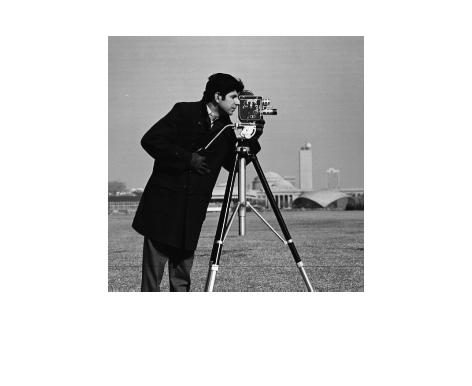

I = imread('cameraman.tif');
imshow(I)

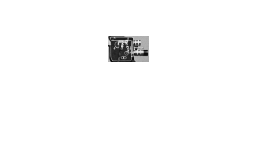


t = I(60:85,130:170 ); % this is your template image
imshow(t)

% write your code here
% functions: imadjust(), imrotate(), xcorr2(), normxcorr2()

% step 1 - get cross correlation / normalized cross correlation
cross_correlation = xcorr2(t, I);
norm_correlation = normxcorr2(t, I);
% step 2 - find the peak value location in the correlation matrix
[x_peak, y_peak] = find(norm_correlation == max(norm_correlation(:)))

x_peak = 85

y_peak = 170

% step 3 -  use function size() to get the size of template image
template_size = size(t)

template_size =     26    41


% step 4 - use insertShape() to display the matched box;

(a) Report results by showing the results of cross-correlation and normalized cross-correlation. Find the instances of template by thresholding the cross-correlation results 

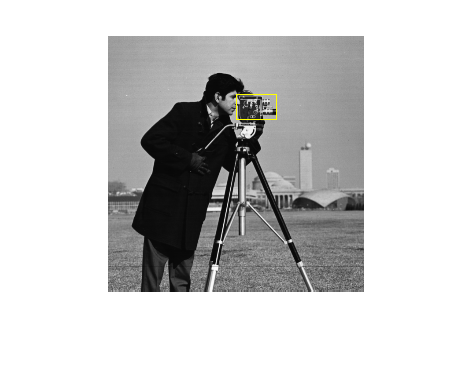

matched_box_a = insertShape(I, 'Rectangle', [y_peak - template_size(1,2), x_peak...
    - template_size(1,1), size(t,2), size(t,1)]);
imshow(matched_box_a)

% for each experiment, display the related search image, template image,
% and matched box

(b) Change the template's intensity but leave the images intensity as in (a) then compare the results obtained in (a)

new_temp = imadjust(t, [0.4; 0.5]);
norm_correlation2 = normxcorr2(new_temp, I);
[x_peak_b, y_peak_b] = find(norm_correlation2 == max(norm_correlation2(:)))

x_peak_b = 85

y_peak_b = 170

new_template_size = size(new_temp)

new_template_size =     26    41


matched_box_b = insertShape(I, 'Rectangle', [y_peak_b - new_template_size(1,2), x_peak_b...
    - new_template_size(1,1), size(new_temp,2), size(new_temp,1)]);
imshow(matched_box_b)

After chanigng the intensity value of the template image, we see no change in the template matching of a gray scale image

(c) Keep the templates intensity the same as in (a) but the image intensity has changed. Compare the results with those obtained in (a) and (b)

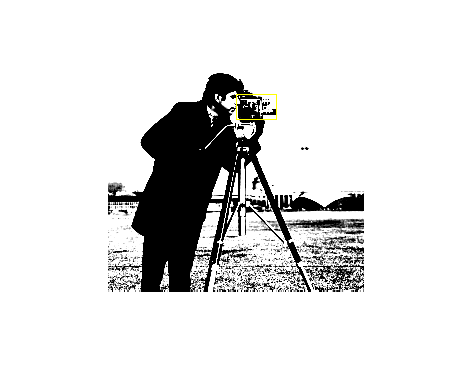

I_c = imadjust(I, [0.4; 0.5]);
matched_box_c = insertShape(I_c, 'Rectangle', [y_peak - template_size(1,2), x_peak...
    - template_size(1,1), size(t,2), size(t,1)]);
imshow(matched_box_c)

After chanigng the intensity value of the image, we see no change in the template matching of a gray scale image

(d) After the intensity of both the image and template have been changed, Compare the results with what was obtained in (a), (b), and (c)

matched_box_d = insertShape(I_c, 'Rectangle', [y_peak - new_template_size(1,2), x_peak...
    - new_template_size(1,1), size(new_temp,2), size(new_temp,1)]);
imshow(matched_box_d)

After chanigng the intensity value of the template and the image, we see no change in the template matching of a gray scale image

(e) Evaluate the effect of rotation on the performance of detection by template matching after the template has been rotated by 90 degrees

rotated_t = imrotate(t, 90);
norm_correlation_rotated = normxcorr2(rotated_t, I);
[x_peak_e, y_peak_e] = find(norm_correlation_rotated == max(norm_correlation_rotated(:)))

x_peak_e = 92

y_peak_e = 91

rotated_template_size = size(rotated_t)

rotated_template_size =     41    26


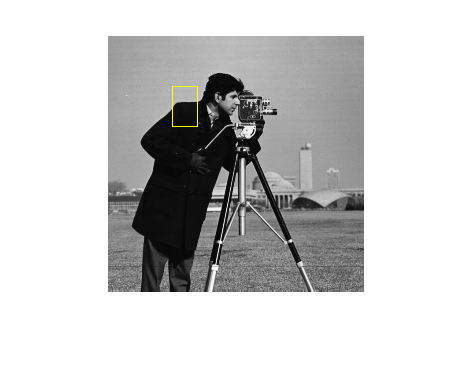

matched_box_e = insertShape(I, 'Rectangle', [y_peak_e - rotated_template_size(1,2), x_peak_e...
    - rotated_template_size(1,1), size(rotated_t,2), size(rotated_t,1)]);
imshow(matched_box_e)

After rotating the template by 90 degrees we see that the template matching algortihm is not as succesful in locating the camera in the image

## Problem 2 - binary image matching

BW  = zeros(100);
b = strel( 'diamond',3);
b = b.Neighborhood;
R = b;

x = [3, 3, 50, 78, 90 ];
y = [5, 60, 20, 80, 1 ];
for i = 1 : length( x )
    BW(y(i):y(i)+6,x(i):x(i)+6) = b;
end

b = strel( 'square',5);
b = b.Neighborhood;

x = [31, 35, 80, 7, 60, 15, 20, 70 ];
y = [5, 60, 60, 80, 30, 20, 50, 66 ];
for i = 1 : length( x )
    BW(y(i):y(i)+4,x(i):x(i)+4) = b;
end

% now, BW is your search image, R is your reference image

% write your code here

% use cross correlation from problem 1 to find matching, record time
before = cputime

before = 1.7442e+03

matching = xcorr2(R, BW);
after = cputime

after = 1.7443e+03

time = after - before

time = 0.0300

% use chamferMatch() to get the distance transform image Q
Q = chamferMatch(BW,R);
before = cputime;
[x_min, y_min] = find(Q == min(Q(:)))

x_min =      5
    60
    20
    80
     1


y_min =      3
     3
    50
    78
    90


after = cputime;
% then find the minimum distance in Q, record time
time = after - before

time = 0.0300

% display all the matching using insertShape()
refSize = size(R)

refSize =      7     7


before1 = cputime;
matching_1 = insertShape(BW, 'Rectangle', [y_min(1,1), x_min(1,1)...
    refSize(1,2), refSize(1,1)]);
imshow(matching_1)
after1 = cputime;
time1 = after1 - before1

time1 = 0.1200

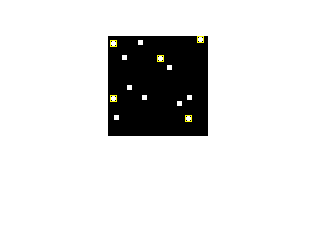

matching_2 = insertShape(matching_1, 'Rectangle', [y_min(2,1), x_min(2,1)...
    refSize(1,2), refSize(1,1)]);
imshow(matching_2)
matching_3 = insertShape(matching_2, 'Rectangle', [y_min(3,1), x_min(3,1)...
    refSize(1,2), refSize(1,1)]);
imshow(matching_3)
matching_4 = insertShape(matching_3, 'Rectangle', [y_min(4,1), x_min(4,1)...
    refSize(1,2), refSize(1,1)]);
imshow(matching_4)
matching_5 = insertShape(matching_4, 'Rectangle', [y_min(5,1), x_min(5,1)...
    refSize(1,2), refSize(1,1)]);
imshow(matching_5)

after = cputime;
time = after-before1

time = 0.4500

The cross correlation and the distance formula took the same amount of CPU time, however, the chamfer matching for each took longer. I learned that the chamfer matching is not as quick as the cross correlation. 